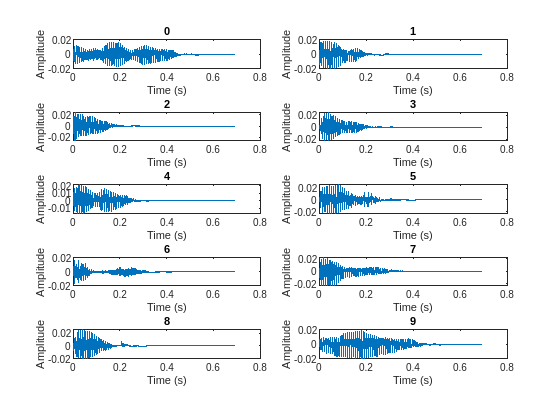

% Duration of the longest audio
maxRows = 0;
for i = 0:9
    [y, Fs] = audioread(sprintf("Samples/%d_16_%d.wav", i, 0));
    [rows, cols] = size(y);
    if(maxRows < rows)
        maxRows = rows;
    end
end
maxDuration = maxRows/Fs;

for i = 0:9
    % y is the audio signal
    % Fs is the sampling frequency
    [y, Fs] = audioread(sprintf("Samples/%d_16_%d.wav", i, 0));
    
    % Ts is the sampling period
    Ts = 1 / Fs;

    % [rows, cols] are the original dimensions of y (there are #rows samples)
    [rows, cols] = size(y);

    % Calculate frame energy
    % Frame size in seconds
    frameSize = 0.01;
    % Get number of samples per frame
    frameSamples = round(frameSize * Fs);
    % Calculate number of frames
    numFrames = floor(rows / frameSamples);
    
    % Calculate frame energy, the sum of squares of the samples in the frame (not the integral because we are in the discrete domain)
    frameEnergy = zeros(numFrames, 1);
    for j = 1:numFrames
        frame = y((j - 1)*frameSamples + 1:j*frameSamples);
        frameEnergy(j) = sum(frame .^ 2);
    end
    % End frame energy calculation

    % Find first index of the first frame with energy above threshold
    energyThreshold = 0.005;
    startFrame = find(frameEnergy > energyThreshold, 1);
    
    % Get the TIME index of the first frame with enery above threshold
    startSample = (startFrame - 1) * frameSamples + 1;

    % Trim y in order to remove low energy values
    y = y(startSample:end);
    % Add silence to the end of y
    [curRows, curCols] = size(y);
    concatY = zeros(maxRows - curRows, 1);
    y = [y; concatY];
        
    
    [curRows, curCols] = size(y);
    % t is the time vector
    t = (0:maxRows-1);
    % t is the time vector in seconds (starts at the first frame that
    % excedes the energy threshold)
    t = (t .* Ts);

    subplot(5, 2, i + 1);
    plot(t, y');
    xlabel('Time (s)');
    ylabel('Amplitude');

    label = sprintf("%d", i);
    title(label);
end